# Husky Localisation using LiDAR in Unstructured Environments

Kamryn Norton 

References: [https://www.mathworks.com/help/vision/ug/build-a-map-from-lidar-data-using-slam.html](https://www.mathworks.com/help/vision/ug/build-a-map-from-lidar-data-using-slam.html) 

                     [https://www.mathworks.com/help/lidar/ug/build-a-map-and-localize-using-segment-matching.html](https://www.mathworks.com/help/lidar/ug/build-a-map-and-localize-using-segment-matching.html) 

% dataFolder2Xtract = "run_1.zip";
% dataFolder = "HuskyLiDAR_Data\";
% % unzip(dataFolder2Xtract, dataFolder);
% % disp('Unzipping LiDAR data (153 MB) ...');

% % 
%  numExpectedFiles =475; 
%  dataFolder = "HuskyLiDAR_Data\";
%  pointCloudFilePattern = fullfile(dataFolder, 'ply', '*.ply');
% 
% % if ~exist("dataFolder2Xtract", 'dir') || numel(dir(pointCloudFilePattern)) < numExpectedFiles
% %     % Unzip the file if the folder does not exist or has fewer files than expected
% %     unzip(zipFilename, unzipFolder);
% % end


### Process files in the directory into pointCloud objects and puts them in a correspondence table

dataFolder = "HuskyLiDAR_Dataindoor3\";
 pointCloudFilePattern = fullfile(dataFolder, 'ply', '*.ply');
plyFiles = dir(pointCloudFilePattern); %get list of directory
%%Error encountered: files were in lexical order
% Extract the numeric part of the file names
fileNumbers = cellfun(@(x) sscanf(x, '%d.ply'), {plyFiles.name});
% Sort the indices based on the extracted numbers
[~, sortedIndices] = sort(fileNumbers);
% Apply the sorted indices to plyFiles to get them in the correct order
plyFiles = plyFiles(sortedIndices);

%Instatiates cell arrays to store data for the table containing .cld data
numFiles = length(plyFiles);
fileNames = cell(numFiles, 1);
pointClouds = cell(numFiles, 1);

%Loops through the ply files and read them
for k = 1:length(plyFiles)
    plyFilename = fullfile(plyFiles(k).folder, plyFiles(k).name);
    pc = pcread(plyFilename);
    % Store the file name and point cloud in the cell arrays
    fileNames{k} = plyFiles(k).name;
    pointClouds{k} = pc;
end
cloudDataTable = table(fileNames, pointClouds, 'VariableNames', {'FileName', 'PointCloud'})

cloudDataTable = 451×2 table
     FileName        PointCloud   
    __________    ________________

    {'0.ply' }    {1×1 pointCloud}
    {'1.ply' }    {1×1 pointCloud}
    {'2.ply' }    {1×1 pointCloud}
    {'3.ply' }    {1×1 pointCloud}
    {'4.ply' }    {1×1 pointCloud}
    {'5.ply' }    {1×1 pointCloud}
    {'6.ply' }    {1×1 pointCloud}
    {'7.ply' }    {1×1 pointCloud}
    {'8.ply' }    {1×1 pointCloud}
    {'9.ply' }    {1×1 pointCloud}
    {'10.ply'}    {1×1 pointCloud}
    {'11.ply'}    {1×1 pointCloud}
    {'12.ply'}    {1×1 pointCloud}
    {'13.ply'}    {1×1 pointCloud}
    {'14.ply'}    {1×1 pointCloud}
    {'15.ply'}    {1×1 pointCloud}


#### Display the first point cloud as an example

%load('PointCloudDataTable.mat')
% pointClouds = cloudDataTable.PointCloud;
% fileNames = cloudDataTable.FileName;
ptCloud = pointClouds{1};
disp(ptCloud)

  pointCloud with properties:

     Location: [67644×3 double]
        Count: 67644
      XLimits: [-34.4939 5.0791]
      YLimits: [-17.6010 56.3310]
      ZLimits: [-0.8091 17.6892]
        Color: []
       Normal: []
    Intensity: []



 dsPercent = 0.1; %downsamplePercent
 regGridSize = 1.5; %changed from 3 to 1.5 

numExpectedFiles =451; 

## SegMatch Implementation

### Preprocess pcloud

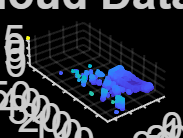


%numExpectedFiles =475; 
% Select a subset of point cloud scans, and split the data to use for map building and for localization.
ptCloudMap = vertcat(pointClouds{1:2:numExpectedFiles-20});%%go to 350 
ptCloudLoc = vertcat(pointClouds{2:2:numExpectedFiles-20}); %have to use vertcat because it is pcd data

ptCloudMapLabels = fileNames(1:2:numExpectedFiles-10);
ptCloudLocLabels = fileNames(2:2:numExpectedFiles-10);

%visualise first pcd
% Visualize the first point cloud.
figure
pcshow(ptCloudMap(1))
title('Viewing Point Cloud Data using pcshow()')


% Select a point cloud from the map for preprocessing.
ptCloud = ptCloudMap(25);

% Set the cylinder radius and ego radius, and pre-processing params.
cylinderRadius = 40;
egoRadius = 1;
 dsPercent = 0.5; %downsamplePercent for downsampling 
 regGridSize = 1.5; %Voxel grid size - changed from 3 to 1.5 

ptCloudNoGround = PreProcess(ptCloud, egoRadius, cylinderRadius)

ptCloudNoGround =   pointCloud with properties:

     Location: [67539×3 double]
        Count: 67539
      XLimits: [-35.7406 6.8014]
      YLimits: [-24.8715 14.8350]
      ZLimits: [-0.1607 8.3776]
        Color: []
       Normal: []
    Intensity: []


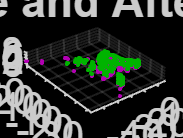


% Visualize the point cloud before and after preprocessing.
figure
pcshowpair(ptCloud,ptCloudNoGround)
title('Point Cloud Before and After Ground Removal')

### Segmentation

Experiment with the following 3 parameters for the ideal segmentation

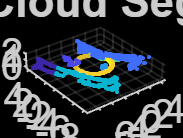

%segmentation params
minNumPoints = 100;
distThreshold = 1;
angleThreshold = 180;

ptCloud = organise(ptCloudNoGround);

%SEGMENTATION
[labels,numClusters] = segmentLidarData(ptCloud,distThreshold, ...
    angleThreshold,'NumClusterPoints',minNumPoints);

% Remove points that contain a label value of 0 for visualization.
idxValidPoints = find(labels);
labelColorIndex = labels(idxValidPoints);
segmentedPtCloud = select(ptCloud,idxValidPoints);

figure
pcshow(segmentedPtCloud.Location,labelColorIndex)
title('Point Cloud Segments')

### Feature extraction

[features,segments] = extractEigenFeatures(ptCloud,labels);
disp(features)

  10×1 eigenFeature array with properties:

    Feature
    Centroid



disp(segments)

  10×1 pointCloud array with properties:

    Location
    Count
    XLimits
    YLimits
    ZLimits
    Color
    Normal
    Intensity



### Segment Matching

ptCloud1 = ptCloudMap(30);
ptCloud2 = ptCloudMap(31);

ptCloud1 = PreProcess(ptCloud1,egoRadius,cylinderRadius);
ptCloud2 = PreProcess(ptCloud2,egoRadius,cylinderRadius);

ptCloud1 = organise(ptCloud1);
ptCloud2 = organise(ptCloud2);

labels1 = segmentLidarData(ptCloud1,distThreshold, ...
    angleThreshold,'NumClusterPoints',minNumPoints);
labels2 = segmentLidarData(ptCloud2,distThreshold, ...
    angleThreshold,'NumClusterPoints',minNumPoints);

### Feature extraction

[features1,segments1] = extractEigenFeatures(ptCloud1,labels1);
[features2,segments2] = extractEigenFeatures(ptCloud2,labels2);

featureMatrix1 = vertcat(features1.Feature);
featureMatrix2 = vertcat(features2.Feature);
indexPairs = pcmatchfeatures(featureMatrix1,featureMatrix2);

centroids1 = vertcat(features1(indexPairs(:,1)).Centroid);
centroids2 = vertcat(features2(indexPairs(:,2)).Centroid);
% 3-D rigid transformation between segment matches using the estgeotform3d function
[tform,inlierPairs] = estgeotform3d(centroids1,centroids2,'rigid'); 

%Visualize the segment matches by using the pcshowMatchedFeatures function.
inlierIdx1 = indexPairs(inlierPairs,1);
inlierIdx2 = indexPairs(inlierPairs,2);
figure
pcshowMatchedFeatures(segments1(inlierIdx1),segments2(inlierIdx2), ...
    features1(inlierIdx1),features2(inlierIdx2))
title('Segment Matches')

%align segments
ptCloudSegments1 = pccat(segments1);
ptCloudSegments2 = pccat(segments2);
tformedPtCloudSegments1 = pctransform(ptCloudSegments1,tform);
figure
pcshowpair(tformedPtCloudSegments1,ptCloudSegments2)
title('Aligned Segments')

TESTING FEATURE MATCHING DISCREPANCIES FOR FULL UNCROPPED PT CLOUD

% k = 225;
% q= k;
% ptCloud1 = ptCloudMap(k);
% storage = [];
% for i = (k+1):numel(ptCloudMap)
% 
%     ptCloud2 = ptCloudMap(i);
% 
%     ptCloud1 = PreProcess(ptCloud1,egoRadius,cylinderRadius);
%     ptCloud2 = PreProcess(ptCloud2,egoRadius,cylinderRadius);
% 
%     ptCloud1 = organise(ptCloud1);
%     ptCloud2 = organise(ptCloud2);
% 
%     labels1 = segmentLidarData(ptCloud1,distThreshold, ...
%         angleThreshold,'NumClusterPoints',minNumPoints);
%     labels2 = segmentLidarData(ptCloud2,distThreshold, ...
%         angleThreshold,'NumClusterPoints',minNumPoints);

### Feature extraction

%     [features1,segments1] = extractEigenFeatures(ptCloud1,labels1);
%     [features2,segments2] = extractEigenFeatures(ptCloud2,labels2);
%     q = q+1;
%     featureMatrix1 = vertcat(features1.Feature);
%     featureMatrix2 = vertcat(features2.Feature);
%     indexPairs = pcmatchfeatures(featureMatrix1,featureMatrix2);
% 
%     storage = vertcat(storage, indexPairs);
%     centroids1 = vertcat(features1(indexPairs(:,1)).Centroid);
%     centroids2 = vertcat(features2(indexPairs(:,2)).Centroid);
% 
%     % 3-D rigid transformation between segment matches using the estgeotform3d function
%     [tform,inlierPairs] = estgeotform3d(centroids1,centroids2,'rigid'); 
% 
%     %Visualize the segment matches by using the pcshowMatchedFeatures function.
%     inlierIdx1 = indexPairs(inlierPairs,1);
%     inlierIdx2 = indexPairs(inlierPairs,2);
%     % figure
%     % pcshowMatchedFeatures(segments1(inlierIdx1),segments2(inlierIdx2), ...
%     %     features1(inlierIdx1),features2(inlierIdx2))
%     % title('Segment Matches')
% 
%     %align segments
%     ptCloudSegments1 = pccat(segments1);
%     ptCloudSegments2 = pccat(segments2);
%     tformedPtCloudSegments1 = pctransform(ptCloudSegments1,tform);
%     % figure
%     % pcshowpair(tformedPtCloudSegments1,ptCloudSegments2)
%     % title('Aligned Segments')
% end
% disp(storage)
% printf('Ended on %d', i)
% 

% table = [k q]
% filenameFeatures = 'featureMatching1.xlsx';
% writematrix(table, filenameFeatures, 'Sheet', 1, 'Range', 'A10')



Creating graph

% featureMatching.Difference = Q-K
% featureMatching

Preprocess

currentViewId = 2;

prevPtCloud = PreProcess(ptCloudMap(currentViewId-1), ...
    egoRadius,cylinderRadius);
ptCloud = PreProcess(ptCloudMap(currentViewId), ...
    egoRadius,cylinderRadius);

%instantiated earlier: dsPercent

prevPtCloudDS = pcdownsample(prevPtCloud,'random',dsPercent);
ptCloudDS = pcdownsample(ptCloud,'random',dsPercent);


Register pcloud

gridStep = 1.5; %size of voxels
relPose = pcregisterndt(ptCloudDS,prevPtCloudDS,gridStep);
locations =[0 0 0]; %to store map locations for analysis
 
vSet2 = pcviewset;
%initialise pose to an identity grid transformation
initAbsPose = rigidtform3d;
%locations = vertcat(locations,initAbsPose.Translation);
vSet2 = addView(vSet2,currentViewId-1,initAbsPose); %add to view
% absolute pose of the second point cloud using the relative pose estimated during registration
absPose2 = rigidtform3d(initAbsPose.A * relPose.A);
locations = vertcat(locations,absPose2.Translation);
storeAbsPose = absPose2;
vSet2 = addView(vSet2,currentViewId,absPose2); %add it to the view set.
%connect the 2 views
vSet2 = addConnection(vSet2,currentViewId-1,currentViewId,relPose);
%transform current pcloud to align to global map
ptCloud = pctransform(ptCloud,absPose2);

Segment pcloud and extract features: straight from example 

prevPtCloud = organise(prevPtCloud);
ptCloud = organise(ptCloud);

%Segment the previous and current point clouds using segmentLidarData.
labels1 = segmentLidarData(prevPtCloud,distThreshold,angleThreshold, ...
    'NumClusterPoints',minNumPoints);
labels2 = segmentLidarData(ptCloud,distThreshold,angleThreshold, ...
    'NumClusterPoints',minNumPoints);
%Extract features from the previous and current point cloud segments using extractEigenFeatures.
[prevFeatures,prevSegments] = extractEigenFeatures(prevPtCloud,labels1);
[features,segments] = extractEigenFeatures(ptCloud,labels2);
%Track the segments and features using a pcmapsegmatch object. Create an empty pcmapsegmatch.
segMap = pcmapsegmatch;
segMap = addView(segMap,currentViewId-1,prevFeatures,prevSegments); %previous features and segments added to pcmapsegmatch
segMap = addView(segMap,currentViewId,features,segments); %current features and segments added

Detect loop closures using findPose

[absPoseMap,loopClosureViewId] = findPose(segMap,absPose2);
isLoopClosure = ~isempty(absPoseMap);
%se the absolute pose of the current view without the accumulated drift, absPoseMap, and the absolute pose of the loop 
%closure view, absPoseLoop, to compute the relative pose between the loop closure poses without the drift.
if isLoopClosure
    absPoseLoop = poses(vSet2,loopClosureViewId).AbsolutePose;
    relPoseLoopToCurrent = rigidtform3d(invert(absPoseLoop).A * absPoseMap.A);
    %Add the loop closure relative pose as a connection using addConnection.
    vSet2 = addConnection(vSet2,loopClosureViewId,currentViewId, ...
    relPoseLoopToCurrent);    

    prevPoses = vSet2.Views.AbsolutePose;

    %create a posegraph from the view & optimise\
    G2 = createPoseGraph(vSet2);     
    optimG2 = optimizePoseGraph(G2,'g2o-levenberg-marquardt');
    vSet2 = updateView(vSet2,optimG2.Nodes);

    %find the transformations from the poses before + after drift correction 
    optimizedPoses2 = vSet2.Views.AbsolutePose;
    
    relPoseOpt = rigidtform3d.empty;
    for k = 1:numel(prevPoses)
        relPoseOpt(k) = rigidtform3d(optimizedPoses2(k).A * invert(prevPoses(k)).A);
    end
    
    segMap = updateMap(segMap,relPoseOpt); %updating the map segments & centroid locations
end

Build map and correct for accumulated drift error - applied to the rest of the scans

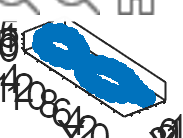


% Set the random seed for example reproducibility.
rng(0)

% Update display every 5 scans.
figure
updateRate = 2;

% Initialize variables for registration.
prevPtCloud = ptCloudDS;
prevPose = rigidtform3d;

% Keep track of the loop closures to optimize the poses once enough loop
% closures are detected.
totalLoopClosures = 0;
tic;

for i = 3:numel(ptCloudMap)
    ptCloud = ptCloudMap(i);
    %disp(i);
    % Preprocess and register the point cloud.
    ptCloud = PreProcess(ptCloud,egoRadius,cylinderRadius);
    ptCloudDS = pcdownsample(ptCloud,'random',dsPercent);
    relPose = pcregisterndt(ptCloudDS,prevPtCloud,gridStep, ... %gridStep defined earlier
        'InitialTransform',relPose);   
    ptCloud = pctransform(ptCloud,absPose2);
    
    % Store the current point cloud to register the next point cloud.
    prevPtCloud = ptCloudDS;    
    
    % Compute the absolute pose of the current point cloud.
    absPose2 = rigidtform3d(absPose2.A * relPose.A);
    locations = vertcat(locations,absPose2.Translation); %add to array of locations 
    % If the vehicle has moved at least 2 meters since last time, continue
    % with segmentation, feature extraction, and loop closure detection.
    if norm(absPose2.Translation-prevPose.Translation) >= 1 %%CHANGE - started at 2
        
        ptCloud = organise(ptCloud);
        % Segment the point cloud and extract features.
        labels = segmentLidarData(ptCloud,distThreshold,angleThreshold, ...
            'NumClusterPoints',minNumPoints);
        [features,segments] = extractEigenFeatures(ptCloud,labels);
        
        % Keep track of the current view id.
        currentViewId = currentViewId+1;

        %fixing eigenvalue error
        if ~isa(features, 'eigenFeature') && ~isempty(features)
                features = eig(features);
        end
        if isempty(features)
            [features,segments] = extractEigenFeatures(ptCloudMap(i-1));
        end

        % Add the view to the point cloud view set and map representation.
        vSet2 = addView(vSet2,currentViewId,absPose2);
        vSet2 = addConnection(vSet2,currentViewId-1,currentViewId, ...
            rigidtform3d(invert(prevPose).A * absPose2.A));
        segMap = addView(segMap,currentViewId,features,segments);
        
        % Update the view set display.
        if mod(currentViewId,updateRate) == 0
            plot(vSet2)
            drawnow
        end

        % Check if there is a loop closure.
        [absPoseMap,loopClosureViewId] = findPose(segMap,absPose2,'MatchThreshold',1, ...
            'MinNumInliers',5,'NumSelectedClusters',4,'NumExcludedViews',150);
        isLoopClosure = ~isempty(absPoseMap);
        
        if isLoopClosure
            totalLoopClosures = totalLoopClosures+1;
            
            % Find the relative pose between the loop closure poses.
            absPoseLoop = poses(vSet2,loopClosureViewId).AbsolutePose;
            relPoseLoopToCurrent = rigidtform3d(invert(absPoseLoop).A * absPoseMap.A);
            vSet2 = addConnection(vSet2,loopClosureViewId,currentViewId, ...
                relPoseLoopToCurrent);
            
            % Optimize the graph of poses and update the map every time 3
            % loop closures are detected.
            if mod(totalLoopClosures,3) == 0
                prevPoses = vSet2.Views.AbsolutePose;
                
                % Correct for accumulated drift: create and optimise pose graph
                G = createPoseGraph(vSet2);
                optimG = optimizePoseGraph(G,'g2o-levenberg-marquardt');
                vSet2 = updateView(vSet2,optimG.Nodes);
                
                % Find the transformations from the poses before and after correcting for drift 
                %and use them to update the map segments and centroid locations using updateMap.
                optimizedPoses2 = vSet2.Views.AbsolutePose;
                relPoseOpt = rigidtform3d.empty;
                for k = 1:numel(prevPoses)
                    relPoseOpt(k) = rigidtform3d(optimizedPoses2(k).A * invert(prevPoses(k)).A);
                end
                segMap = updateMap(segMap,relPoseOpt);
                
                % Update the absolute pose after pose graph optimization.
                absPose2 = optimizedPoses2(end);
            end
        end
        prevPose = absPose2;
    end
end

timetobuildmap =toc;

### Using the example code for localisation on a map built 

## Localize Vehicle in Known Map

The preprocessing steps for localization using SegMatch are the same preprocessing steps used for map building. Since the algorithm relies on consistent segmentation, use the same segmentation parameters for best results.

ptCloud = ptCloudMap(200);

% Preprocess the point cloud.
ptCloud = PreProcess(ptCloud,egoRadius,cylinderRadius);
ptCloud = organise(ptCloud);
% Segment the point cloud and extract features.  
labels = segmentLidarData(ptCloud,distThreshold,angleThreshold, ...
    'NumClusterPoints',minNumPoints);
features = extractEigenFeatures(ptCloud,labels);

Because there is no position estimate for the vehicle, you must use the extent of the map for initial vehicle localization. Select the extent of the map to localize for the first time using [`selectSubmap`](docid:lidar_ref#mw_5cf81d8f-4eec-4199-a1fb-ece3b50a60db).

 segMap = selectSubmap(segMap,[segMap.XLimits segMap.YLimits segMap.ZLimits]);

Use the [`findPose`](docid:lidar_ref#mw_5fc1ef80-253d-46ae-909b-1ca69b88aebd) object function of [`pcmapsegmatch`](docid:lidar_ref#mw_acc8abe2-15e0-4f27-a991-6cce7d217bc4) to localize the vehicle on the prebuilt map.

tic;
 absPoseMap = findPose(segMap,features,'MatchThreshold',30,'MinNumInliers',3)

absPoseMap =   rigidtform3d with properties:

    Dimensionality: 3
       Translation: [-4.2357 9.1190 1.0243]
                 R: [3×3 double]
                 A: [4×4 double]


timeforsegmatch = toc

timeforsegmatch = 0.9126

Visualize the mac, and use [`showShape`](docid:vision_ref#mw_0d2c09e0-7e4d-4a2b-8d39-165310f8211a) to visualize the vehicle on the map as a cuboid.

mapColor = [0 0.4 0.7];
mapSegments = pccat(segMap.Segments);



figure;
hAxLoc = pcshow(mapSegments.Location,mapColor); %plot(vSet2)
title('Localization on a Prebuilt Map')
view(2)

poseTranslation = absPoseMap.Translation;
quat = quaternion(absPoseMap.Rotation','rotmat','point');
theta = eulerd(quat,'ZYX','point');
pos = [poseTranslation 1 1 1 theta(2) theta(3) theta(1)];
showShape('cuboid',pos,'Color','green',...%'Parent',hAxLoc, ...
    'Opacity',0.8,'LineWidth',0.5)

To improve localization speed for the rest of the scans, select a submap using [`selectSubmap`](docid:lidar_ref#mw_5cf81d8f-4eec-4199-a1fb-ece3b50a60db).

submapSize = [65 65 200];
sMap = selectSubmap(segMap,poseTranslation,submapSize);

Continue localizing the vehicle using the rest of the point cloud scans. Use [`isInsideSubmap`](docid:lidar_ref#mw_ad2e5e94-7211-40cf-b0fd-c85e681986b6) and [`selectSubmap`](docid:lidar_ref#mw_5cf81d8f-4eec-4199-a1fb-ece3b50a60db) to keep the submap updated. If there are not enough segments to localize the vehicle using segment matching, use registration to estimate the pose. 

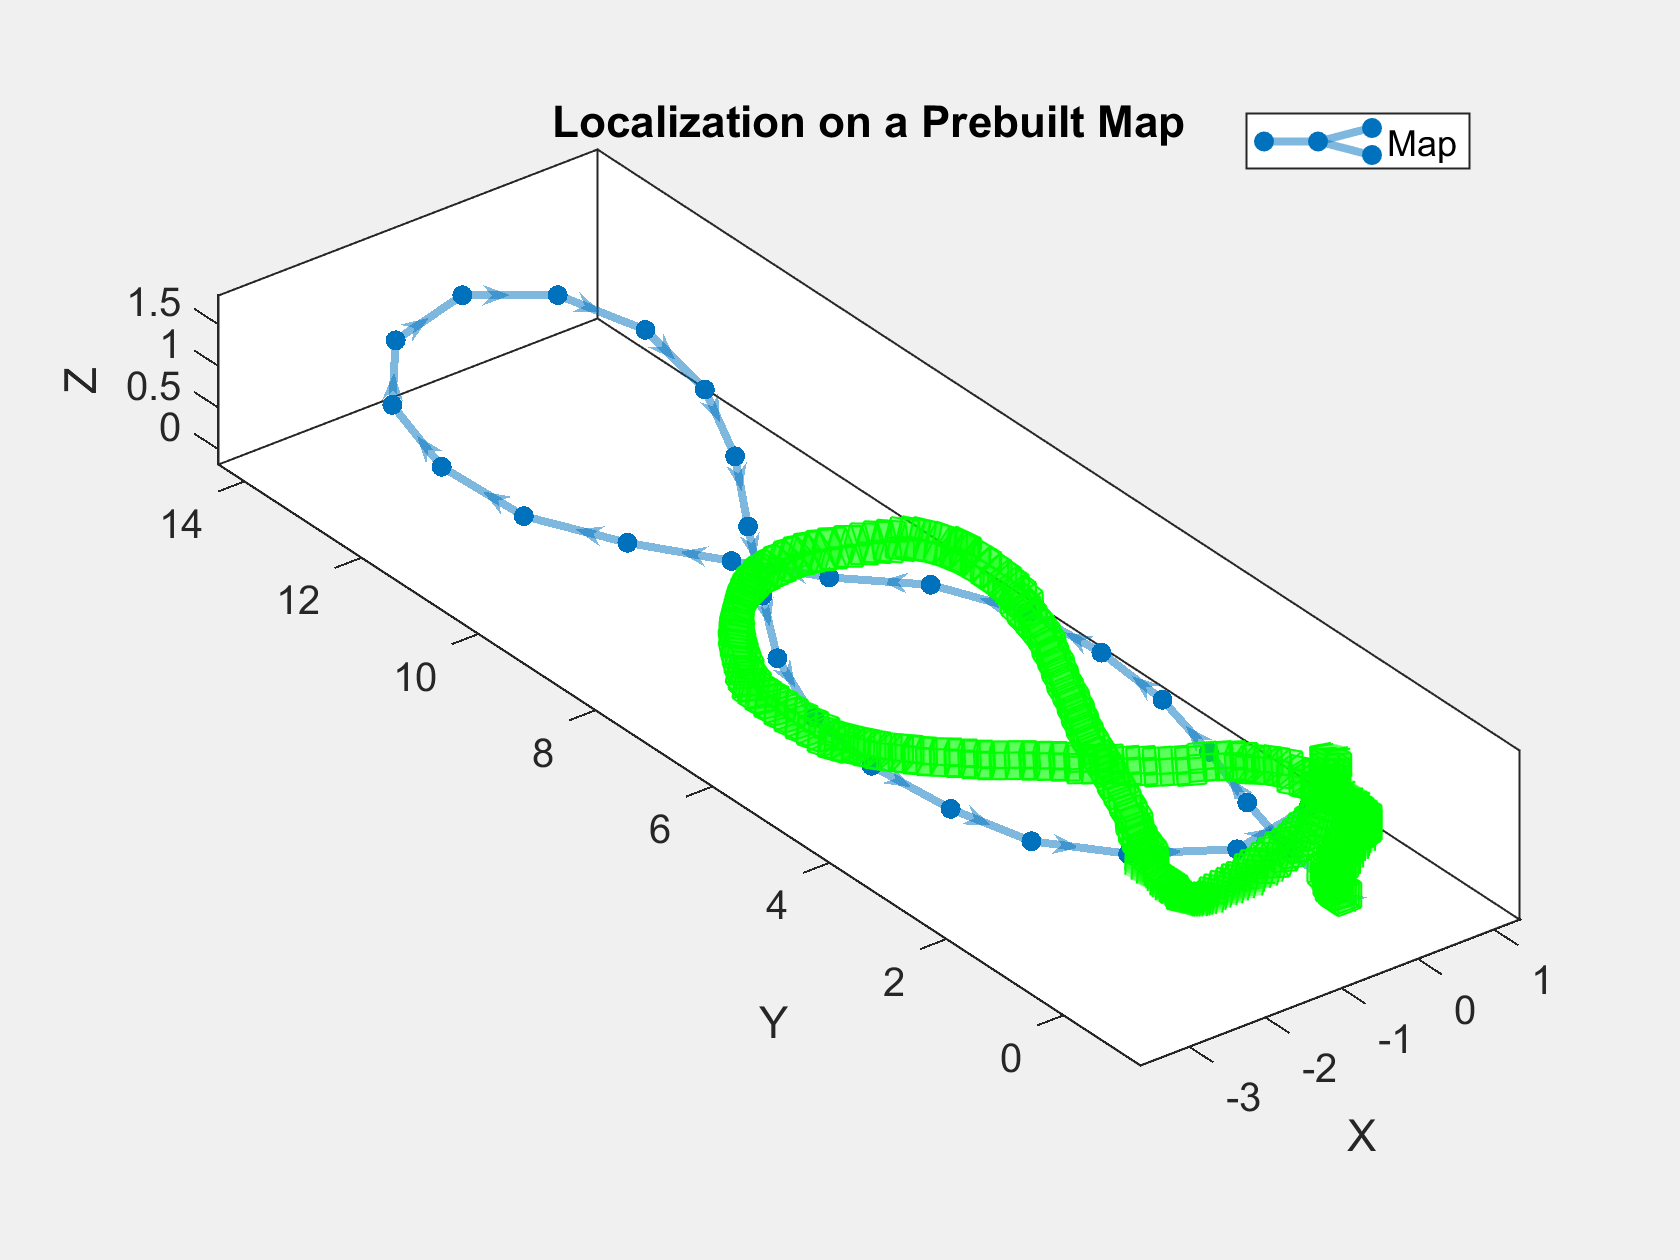

% Visualize the map.
figure('Visible','on')
hAx = plot(vSet2);%pcshow(mapSegments.Location,mapColor);

title('Localization on a Prebuilt Map')

% Set parameter to update submap.
%submapThreshold = 20;
tic;
% Initialize the poses and previous point cloud for registration.
prevPtCloud = ptCloud;
relPose = rigidtform3d;
prevAbsPose = rigidtform3d;
localisedPoses = [0 0 0];
segMatchLocations = [0 0 0];
% Segment each point cloud and localize by finding segment matches.
for n = 2:numel(ptCloudLoc)
    ptCloud = ptCloudLoc(n);

    % Preprocess the point cloud.
    ptCloud = PreProcess(ptCloud,egoRadius,cylinderRadius);
    ptCloud = organise(ptCloud);
    % Segment the point cloud and extract features.
    labels = segmentLidarData(ptCloud,distThreshold,angleThreshold, ...
        'NumClusterPoints',minNumPoints);
    features = extractEigenFeatures(ptCloud,labels);

    % Localize the point cloud using SegMatch
    smLoc = findPose(sMap,features,'MatchThreshold',30,'MinNumInliers',3);
    if isempty(smLoc)
        smLoc = [0 0 0];
        segMatchLocations = vertcat(segMatchLocations,smLoc);
    else
        segMatchLocations = vertcat(segMatchLocations,smLoc.Translation);
    end
    %absPoseMap = smLoc
    % Do registration when the position cannot be estimated with segment
    % matching.
    %if isempty(absPoseMap)

        relPose = pcregisterndt(ptCloud,prevPtCloud,gridStep, ...
            'InitialTransform',relPose);
        absPoseMap = rigidtform3d(prevAbsPose.A * relPose.A);
       %continue;
    %end
    localisedPoses = vertcat(localisedPoses, absPoseMap.Translation);
    hold on;
    % Display position estimate in the map.
    poseTranslation = absPoseMap.Translation;
    quat = quaternion(absPoseMap.Rotation','rotmat','point');
    theta = eulerd(quat,'ZYX','point');
    pos = [poseTranslation 0.3 0.3 0.3 theta(2) theta(3) theta(1)];
    showShape('cuboid',pos,'Color','green',...%'Parent',hAx,
        'Opacity',0.4,'LineWidth',0.5)
    legend('Map', 'Location', 'best')
    %Determine if selected submap needs to be updated.
    % [isInside,distToEdge] = isInsideSubmap(sMap,poseTranslation);
    % needSelectSubmap = ~isInside ...                      % Current pose is outside submap.
    %     || any(distToEdge(1:2) < submapThreshold);        % Current pose is close to submap edge.
    % 
    % % Select a new submap.
    % if needSelectSubmap
    %     sMap = selectSubmap(sMap,poseTranslation,submapSize);
    % end

    prevAbsPose = absPoseMap;
    prevPtCloud = ptCloud;
end

%hold off;
timeforregistration =toc;

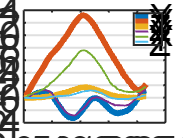



figure;
plot(locations,'LineWidth', 1.5)
hold on
plot(localisedPoses)
legend("X Map", "Y Map", "Z Map", "X Loc", "Y Loc", "Z Loc", 'Location','best')
title('NDT Registration Localisation Positions and Map Positions Over All Samples')
xlabel("Sample")
ylabel("Position (m)")
hold off

set(gca,"XGrid","off","YGrid","on")



%SegMatch Localisation vs Map
figure;
plot(segMatchLocations)
hold on
plot(locations, 'LineWidth', 2)
legend("X SM", "Y SM", "Z SM","X Map", "Y Map", "Z Map", 'Location','best')
title('SegMatch Localisation Positions and Map Positions Over All Samples')
xlabel("Sample")
ylabel("Position (m)")
hold off


%Final Error
xError = abs(locations(end-1,1)-localisedPoses(end,1))

xError = 0.0590

yError = abs(locations(end-1,2)-localisedPoses(end,2))

yError = 0.3263

zError = abs(locations(end-1,3)-localisedPoses(end,3))

zError = 0.1485

barLabels= categorical({'X','Y','Z'});
barData = [xError yError zError];
clear bar;
figure;
bar(barLabels, barData, 0.2)

set(gca,"XGrid","off","YGrid","on")
grid minor
text(1:length(barData),barData,num2str(barData'),'vert','bottom','horiz','center'); 

title("Graph Showing the Final Error for Localisation")
xlabel("Coordinate")
ylabel("Final Error (m)")


%Distances
store = [];
outliers = [];
for i=1:numel(localisedPoses)
     temp = vecnorm(locations(i)- localisedPoses(i));
     if temp<10
        store(i) = temp;
     else 
         outliers(i) = temp;
     end 
end
figure;
plot(store)
hold on;
%plot(outliers)
hold off;

title("Distance Between Localised Point and Map Point")
xlabel("Sample")
ylabel("Distance (m)")

ax = gca;


%Write data to spreadsheet to not lose it 
filename = 'testData3.xlsx';

%T = table(localisedPoses, locations, segMatchLocations);
%writetable(T, filename, 'Sheet',2,'Range', 'B1');
% writematrix(localisedPoses, filename, 'Sheet', 5, 'Range', 'B2');
% writematrix(locations, filename, 'Sheet', 5, 'Range', 'E2');
% writematrix(segMatchLocations, filename, 'Sheet', 5, 'Range', 'H2')
times = table(timetobuildmap, timeforregistration,timeforsegmatch);
writetable(times, filename, 'Sheet', 5, 'Range', 'A1');

## Localise vehicle in the known map

% % indicesOfLoc = randi([1 328],15,1); %10 random integers/locations
% % indicesOfLoc = sort(indicesOfLoc);
% tic;
% len = length(ptCloudLoc)
% %for map graphing:
% extractedNumbers = zeros(1, len);
% extractedNumbersLoc = zeros(1, len);
% timearray = zeros(1, len);
% timearrayCorrect = zeros(1, len);
% tformLocArray = [];
% tformLocArrayValid = [];
% rmsestoreArray=[];
% figHandle = figure;
% 
% % % 

Absolute poses were relative, now fixing

% % initAbsPose = initial absolute pose
% %storeAbsPose = abs pose of 2nd pcd
% 
% 
% for i = 1:20:len
%     %indexOfLoc = indicesOfLoc(i);
%     ptCloud = ptCloudLoc(i);
%     nameLoc = string(ptCloudLocLabels{i});
%     %MAP GRAPHING
%     % Extract number from the file name using regular expression
%     number = regexp(nameLoc, '\d+', 'match');
%     % Convert the extracted number from cell to double
%     extractedNumbers(i) = str2double(number{1});
% 
%     tic;
%     % Preprocess the point cloud.
%     ptCloud = PreProcess(ptCloud,egoRadius,cylinderRadius);
%     %organise for segmentation
%     ptCloud = organise(ptCloud);
%     % Segment the point cloud and extract features.  
%     labels = segmentLidarData(ptCloud,distThreshold,angleThreshold, ...
%         'NumClusterPoints',minNumPoints);
%     [featuresLoc,segmentsLoc] = extractEigenFeatures(ptCloud,labels);
% 
%     %segMap = selectSubmap(segMap,[segMap.XLimits segMap.YLimits segMap.ZLimits]);
%     %[absPoseMap,viewID] = findPose(segMap, featuresLoc, 'MatchThreshold', 3, 'MinNumInliers',5); %%change here
%        [absPoseMap,~,inlierFeatures,inlierSegments] = findPose(segMap, featuresLoc,segmentsLoc, 'MatchThreshold', 3, 'MinNumInliers',5); %%change here
% 
%     if isempty(absPoseMap)
%             disp('absPoseMap empty')
%     else 
%         poseTranslation = absPoseMap.Translation;
%         quat = quaternion(absPoseMap.Rotation','rotmat','point');
%         theta = eulerd(quat,'ZYX','point');
%         %pos = [poseTranslation 5 9 3.5 theta(2) theta(3) theta(1)];
%         pos = [poseTranslation 0.99 0.67 0.39 theta(2) theta(3) theta(1)]; %changed size to match husky
%        % showShape('cuboid',pos,'Color','red','Parent',hAxLoc,'Opacity',0.8,'LineWidth',0.5)
%         elapsedtime = toc;
%         fprintf('Elapsed time is %f seconds.', elapsedtime)
%         timearray(i) = elapsedtime;
%         sprintf('The file input (ground truth) was: %s',nameLoc)
%         %Applying ICP for verification
%         % Iterate through all stored point clouds and their poses to find the closest match
%         minDistance = inf;
%         matchingFile = '';
%         distanceArray = []; %empty array for graphing
%         indexArray = [];
%         %candidates =cell(1, 10);
%         w =1; j=1;
%         disp('With a location of: ')
%         poseTranslation
% 
%         minError = inf;
%          minErrorFile = '';
%         localisingCloud = ptCloud;
%         for k = 1:2:length(ptCloudMap) 
% 
%             % Retrieve the stored point cloud and its associated pose
%             storedPtCloud = ptCloudMap(k);
%             % Preprocess the point cloud.
%             storedPtCloud = PreProcess(storedPtCloud,egoRadius,cylinderRadius);
%             storedPtCloud = organise(storedPtCloud);
% 
%             % Apply ICP to align the file's point cloud with the given point cloud
%             [tform,~ , rmse] = pcregistericp(storedPtCloud, localisingCloud, 'Metric','pointToPoint','Extrapolate', true);
% 
%             % Check if this error is the smallest found so far
%             if rmse ==0
%                 minError = rmse;
%                 minErrorFile = ptCloudMapLabels{k};
%                 break;
%             elseif rmse < minError
%                 % Update minError and minErrorFile
%                 minError = rmse;
%                 minErrorFile = ptCloudMapLabels{k};
%                 tform_store = tform;
%                 rmsestore = rmse;
%             end
%         end
%         tformLocArray(end+1, :) = absPoseMap.Translation;
%         tformLocArrayValid(end+1,:) = tform_store.Translation;
%         rmsestoreArray(end+1)=rmsestore;
%         % Display the matching file
%         fprintf('The file with the most similar point cloud is %s with an RMSE of %.2f.\n', minErrorFile, minError);
%         %plot(indexArray, distanceArray, 'b-')
% 
%         %MAP GRAPHING
%         % Extract number from the file name using regular expression
%         numberLoc = regexp(minErrorFile, '\d+', 'match');
%          % Convert the extracted number from cell to double
%         extractedNumbersLoc(i) = str2double(numberLoc{1});
%         % 
%         if((extractedNumbersLoc(i)-extractedNumbers(i))<=5) %if they are within 5 files of one another
%             timearrayCorrect(i) = elapsedtime;
% 
%         end
% 
% 
%                       figure(figHandle); % create a new figure
% 
%             hold on
%             plot(vSet2)
% 
%             plot(absPoseMap.Translation(1),absPoseMap.Translation(2), 'r*')
%             hold off
%             drawnow;
%     end 
% 
% end 

% 
% overAllTime = toc;
% disp(extractedNumbers)
% disp(extractedNumbersLoc)
% disp(timearray)
% disp(timearrayCorrect)
% timearrayCorrect = timearrayCorrect(timearrayCorrect ~= 0);
% avgCorrect = mean(timearrayCorrect)
% avgAll = mean(timearray)

Distances calculation (euclidean) between SegMatch Localisation and ICP transformation & a plot

% ditance_array = [];
% for i=1:size(tformLocArray,1) %loop through rows
%     currentrowLoc = tformLocArray(i,:);
%     currentrowVer = tformLocArrayValid(i,:);
%     distance = vecnorm(currentrowLoc - currentrowVer, 2, 2);
%     distance_array(i) = distance;
% end
% figure;
% plot(distance_array, 'b-', 'LineWidth',1);

Including zero values

% % Create a new figure
% figure;
% %x = [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15];
% x = 1:length(extractedNumbers)
% % Plotting the map points
% plot(x, extractedNumbers, 'bo-', 'LineWidth', 2); 
% hold on;
% y = extractedNumbersLoc;
% y(y == 0) = NaN;
% % Plotting the localized points
% plot(x, y, 'rx-', 'LineWidth', 1);
% 
% % % Loop through each point to connect map and localized points with a line
% % for i = 1:length(extractedNumbers)
% %     plot(extractedNumbers(i), extractedNumbersLoc(i), 'k--');
% % end
% 
% % Adding labels and title
% xlabel('Index');
% ylabel('Distance(File)');
% title('Map and Localized Points with non-Localised');
% legend('Map Points', 'Localized Points', 'Location', 'Best');
% 
% % Show grid
% grid on;
% 
% % Display the plot
% hold off;

Excluding zero values (findPose unsuccessful)

% extractedNumbers = extractedNumbers(extractedNumbersLoc ~=0);
% 
% extractedNumbersLoc = extractedNumbersLoc(extractedNumbersLoc ~=0);
% 

Some Performance Metrics

% numberProcessed = length(extractedNumbers)
% numberCorrect = length(timearrayCorrect)
% accuracy = numberCorrect/numberProcessed;
% fprintf('The percentage accuracy is %.2f%%\n', accuracy*100);
% fprintf('The distance average is %.2f%\n', mean(distance_array));
% 

A plot of the accuracy

% % Create a new figure
% figure;
% x =1:length(extractedNumbers)
% % Plotting the map points
% plot(x, extractedNumbers, 'bo-', 'LineWidth', 2); 
% hold on;
% 
% % Plotting the localized points
% plot(x, extractedNumbersLoc, 'rx-', 'LineWidth', 1);
% 
% % % Loop through each point to connect map and localized points with a line
% % for i = 1:length(extractedNumbers)
% %     plot(extractedNumbers(i), extractedNumbersLoc(i), 'k--');
% % end
% 
% % Adding labels and title
% xlabel('Index');
% ylabel('Distance(File)');
% title('Map and Localized Points');
% legend('Map Points', 'Localized Points', 'Location', 'Best');
% 
% % Show grid
% grid on;
% 
% % Display the plot
% hold off;

ptCloudView = ptCloudMap(30);

function ptCloudNoGround = PreProcess(ptCloud,egoRadius,cylinderRadius)

    % Select the points inside the cylinder radius and outside the ego radius.
    cylinderIdx = findPointsInCylinder(ptCloud,[egoRadius cylinderRadius]);
    ptCloud = select(ptCloud,cylinderIdx,'OutputSize','full');
    
    % Remove ground.
    [~,ptCloudNoGround] = segmentGroundSMRF(ptCloud,'ElevationThreshold',0.5);
    
    %return ptCloudNoGround;
end

function OrganisedPCloud = organise(ptCloud)
    %to organise the point cloud for the segmentations - WERE ISSUES HERE
    horizontalRes = 512; %channels in horizontal direc, 512 or 1024
    params = lidarParameters('VLP32C', horizontalRes);
    OrganisedPCloud = pcorganize(ptCloud,params);
end

function plotSegMatchLocalization(segMatchLocalization, index)
    % Plot all SegMatch localization results up to the current index
    plot3(segMatchLocalization(1:index,1), segMatchLocalization(1:index,2), segMatchLocalization(1:index,3), 'ro-');
    % Highlight the current localization result
    plot3(segMatchLocalization(index,1), segMatchLocalization(index,2), segMatchLocalization(index,2),'ro', 'MarkerSize', 10, 'LineWidth', 2);
end

function plotICPLocalization(icpLocalization, index)
    % Similar to plotSegMatchLocalization, but for ICP results
    % Plot all ICP localization results up to the current index
    plot3(icpLocalization(1:index,1), icpLocalization(1:index,2), icpLocalization(1:index,3), 'ro-');
    % Highlight the current localization result
    plot3(icpLocalization(index,1), icpLocalization(index,2), icpLocalization(index,3) ,'ro', 'MarkerSize', 10, 'LineWidth', 2);
end